% clear
% 
% % Read img file
% img = imread("../db/DB1/db1_07.jpg");
% 
% % Normalize colors
% img_gw = gray_world(img);
% 
% % Create facemask 
% face_mask = facemask(img_gw);
% imshow(face_mask)
% 
% %Find eyes and a mouth
% eyes = eyemap(img_gw);
% eye_mask = eyemask((eyes),face_mask);
% %eye_mask = hybrid(img_gw);
% imshow(eye_mask)
% 
% mouth = mouth_map(img_gw);
% mouth_mask = mouthmask(mouth) & face_mask;
% imshow(mouth_mask)
% 
% [x,y] = mouth_index(mouth_mask)
% 
% [indexX,indexY] = eye_index(eye_mask)
% % Replace with actual coordinates
% mouth_center = [x, y]; 
% [eye1 , eye2, angle] = findEyePair(indexX,indexY,mouth_center)
% 
% % Visualize the original image with detected eyes and mouth
% figure;
% imshow(img);
% hold on;
% viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
% plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

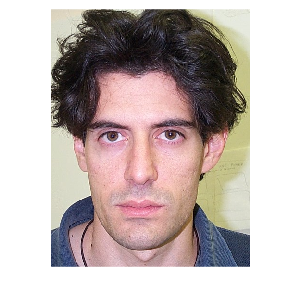

clear
%Problem with: 10
% Read img file
img = imread("../db/DB1/db1_14.jpg");
imshow(img)

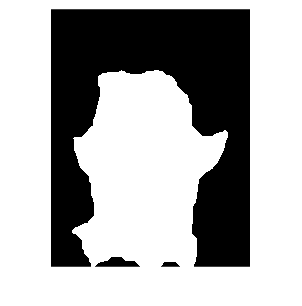


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

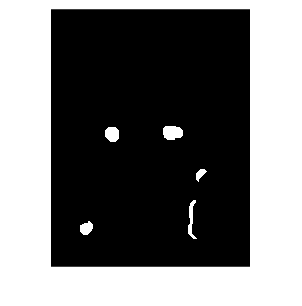


%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask((eyes),face_mask);

imshow(eye_mask)

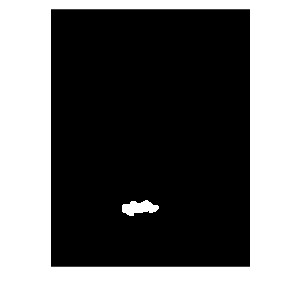


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask)

x = 414

y = 185


[indexX,indexY] = eye_index(eye_mask)

indexX =    74.0441  128.1176  253.7115


indexY =   456.2134  261.1765  257.8977


% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
[~, sorted_indices] = sort(distances)

sorted_indices =      3
     2
     1


selected_eye_indices = [];
% Iterate through sorted indices to find the eyes where the mouth index is between them
for i = 1:length(sorted_indices)-1
    left_eye_index = min(sorted_indices(i), sorted_indices(i+1));
    right_eye_index = max(sorted_indices(i), sorted_indices(i+1));

    % Check if both eyes are between the mouth index
    if eye_centers(left_eye_index, 1) < x && eye_centers(right_eye_index, 1) > x
        selected_eye_indices = [left_eye_index, right_eye_index];
        break;  % Break the loop when the condition is satisfied
    end
end
%selected_eye_indices = sorted_indices(1:2)
%selected_eye_indices = sorted_indices(find(eye_centers(sorted_indices, 1) < x & eye_centers(sorted_indices, 2) > y, 2));

% Extract the coordinates of the selected eyes
selected_eyes = [indexX(selected_eye_indices), indexY(selected_eye_indices)];

viscircles([selected_eyes(1),selected_eyes(3)],10)

Index exceeds the number of array elements. Index must not exceed 0.

viscircles([selected_eyes(2),selected_eyes(4)],10)

eye1 = [selected_eyes(1),selected_eyes(3)];
eye2 = [selected_eyes(2),selected_eyes(4)];

figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')